# №1 1)

p = [1 4 -2 -14 -3 -18];
%%syms x;
%%poly2sym(p,x)
disp(factor(poly2sym(p)));

$$\left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

## №2 1)

syms x;
l = x*exp(-x);
disp(limit(l,x,+inf));

$$0$$

## №2 2)

syms x;
l = tan(x)^(tan(2*x));
disp(limit(l,x,pi/4));

$${\mathrm{e}}^{-1}$$

## №3 5)

syms x;
f = (1/6)*log((x-3)/(x+3));
df = diff(f);
disp(simplify(df));

$$\frac{1}{x^{2}-9}$$

## №4 1)

syms x;
f = sqrt(1-x^2)/x^2;
disp(int(f));

$$-\mathrm{asin}\left(x\right)-\frac{\sqrt{1-x^{2}}}{x}$$

## №4 2)

syms x;
f = 1/(sin(x))^3;
disp(int(f));

$$\frac{\log\left(\tan\left(\frac{x}{2}\right)\right)}{2}-\frac{\cos\left(x\right)}{2\,{\sin\left(x\right)}^{2}}$$

## № 5 1)

syms n; syms m;
s = symsum(1/(n^2),n,1,m);
disp(limit(s,m,inf));

$$\frac{\pi^{2}}{6}$$

## №6 2)

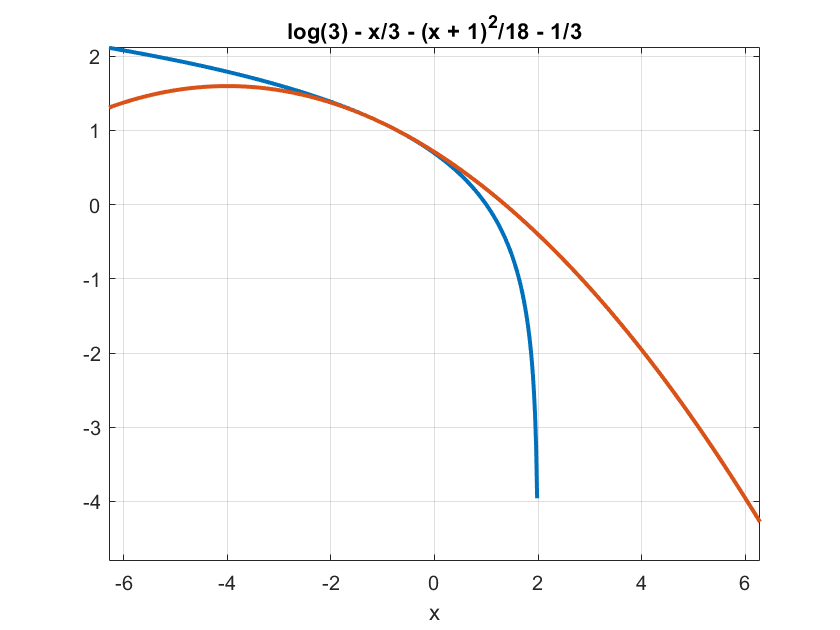

syms x;
a = -1; n = 3;
f = log(2-x);
t = taylor(f, x, a,'Order',n);
x = -10:0.1:10;
g(1) = ezplot(f);
hold on; grid on;
g(2) = ezplot(t);
set(g, 'LineWidth', 2);
hold off;

disp(t);

$$\log\left(3\right)-\frac{x}{3}-\frac{{\left(x+1\right)}^{2}}{18}-\frac{1}{3}$$

## №7

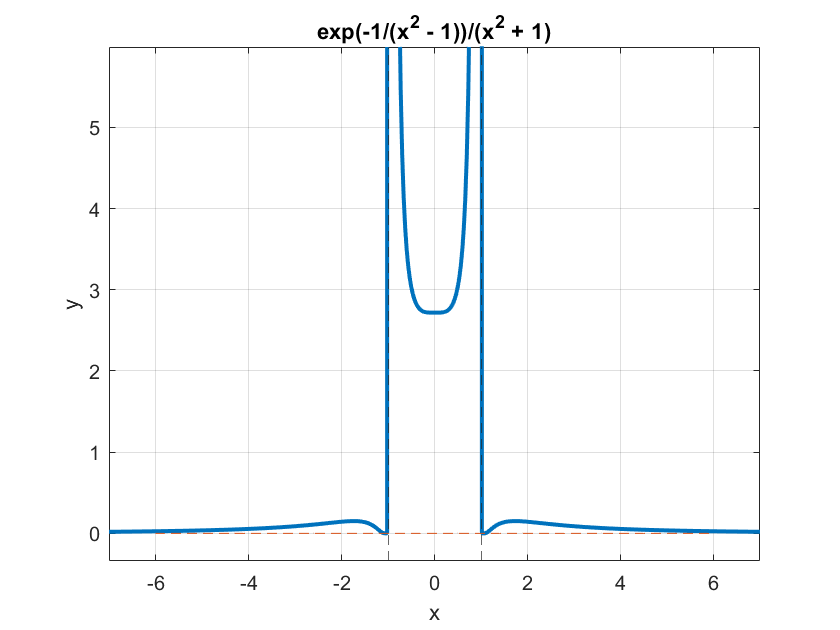

syms x;
f = exp(1/(1-x^2))/(1+x^2);
g = ezplot(f,-7,7);
set(g,'LineWidth',2);
hold on; grid on; ylabel('y');
k = limit(f/x,x,-inf);
b = limit(f-k*x,x,-inf);
y_n = k*x+b;
x_v = [-1 0 1];
x_r = roots(x_v);
v_as(1) = limit(f,x,x_r(1),'right');
v_as(2) = limit(f,x,x_r(2),'right');
v_as(3) = limit(f,x,x_r(1),'left');
v_as(4) = limit(f,x,x_r(2),'left');
%%disp(v_as);
n = 1;
for i = 1:4
    if (v_as(i) ~= inf) 
        y(n) = v_as(i); 
        n = n+1;
    end
end
%%disp(y);
x_plot = -6:0.1:6;
y_n = y_n.*x_plot;
plot(x_plot,y_n,'--');
xline(x_r(1),'--');
xline(x_r(2),'--');

xlim([-7.0 7.0])
ylim([-0.34 5.99])
hold off;

## №8

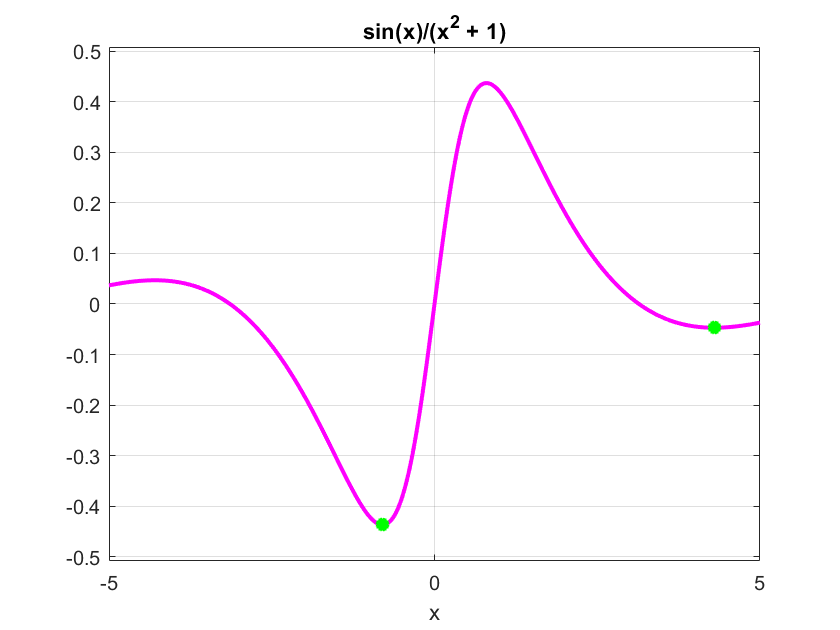

syms x;
f = sin(x)/(x^2+1);
fun = @(X)sin(X)/(X^2+1);
gr = ezplot(f,[-5,5]);
hold on;
gr.LineWidth = 2;
gr.Color = 'm';
[x_m1,y_m1] = fminbnd(fun, -5, 0);
[x_m2,y_m2] = fminbnd(fun, 0, 5);
plot(x_m1,y_m1,'g*',x_m2,y_m2,'g*','LineWidth',4);
grid on;
hold off;

## №9

syms t u;
X = t*cos(u)*cos(u);
Y = t^2*cos(u)*sin(u);
Z = t^3*sin(u);

dx = diff(X,t);
dx_2 = diff(dx,t);

dy = diff(Y,t);
dy_2 = diff(dy,t);

dz = diff(Z,t);
dz_2 = diff(dz,t);

sum_det = simplify((det([dy dz;dy_2 dz_2]))^2+(det([dx dz;dx_2 dz_2]))^2+(det([dx dy;dx_2 dy_2]))^2);
curv = simplify(sum_det/(dx^2+dy^2+dz^2)^3);
disp(sqrt(curv));

$$2\,\sqrt{\frac{{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}\,\left(9\,t^{4}\,{\sin\left(u\right)}^{2}+9\,t^{2}\,{\cos\left(u\right)}^{2}+{\cos\left(u\right)}^{4}\right)}{{\left(9\,t^{4}\,{\sin\left(u\right)}^{2}+4\,t^{2}\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}+{\cos\left(u\right)}^{4}\right)}^{3}}}$$


dx_3 = diff(dx_2,t);
dy_3 = diff(dy_2,t);
dz_3 = diff(dz_2,t);

tor = simplify(det([dx dy dz;dx_2 dy_2 dz_2;dx_3 dy_3 dz_3]));
tor = simplify(tor/sum_det);
disp(tor);

$$\frac{3\,\cos\left(u\right)}{-9\,t^{4}\,{\cos\left(u\right)}^{2}+9\,t^{4}+9\,t^{2}\,{\cos\left(u\right)}^{2}+{\cos\left(u\right)}^{4}}$$